clear
close all
clc

**Opgave 17:**

Til et symmetrisk Chebyshev I-båndpasfilter er kravene:

fns = 4000;
fnp = 12500;
fop = 32000;
fos = 100000;
BWp = fop-fnp

BWp = 19500

BWs = fos-fns

BWs = 96000


As = 20; % Referencen er ved +20 dB == 0. As er altså ved -20 dB
Ap = 1;
A_rip = 1;

17.1: Realiser filteret aktivt ved kaskadekobling af det nødvendige antal 2. ordens filtre. De aktive filtre skal være af typen Infinite Gain Multiple Feedback (IGMF).

Først findes centerfrekvensen

f0 = sqrt(fnp*fop)

f0 = 20000

Den er altså 20 kHz. Herefter skal et tilsvarende lavpasfilter findes.

Lavpasfilterets knækfrekvens er lig BWp, mens dets stopfrekvens er BWs, altså hhv. 19500 Hz og 96000 Hz. Værdierne normeres, således at BWp = 1. Derfor:

wlpnp = BWp/BWp % VIDST IKKE NØDVENDIGT

wlpnp = 1

wlpns = BWs/BWp

wlpns = 4.9231

Dette lavpasfilter skal altså findes.

[nlp,wn] = cheb1ord(BWp,BWs,Ap,As,'s') % Da dette giver n = 2, er båndpasfilteret altså fjerdeordens

nlp = 2

wn = 19500

[z,p,k] = cheb1ap(nlp,A_rip);
[numLPn,denLPn] = zp2tf(z,p,k);
Hslpn = tf(numLPn,denLPn);
[numBPn,denBPn] = lp2bp(numLPn,denLPn,1,(32-12.5)/20);

Det fundne lavpasfilter er normeret. Det denormeres derfor: //// IKKE DENORMER HER, GIVER FEJL!

s_n = tf('s')/wn;
Hslp = 0.9826/(s_n^2+1.098*s_n+1.103)


Hslp =
 
              7.286e12
  ---------------------------------
  19500 s^2 + 4.175e08 s + 8.179e12
 
Continuous-time transfer function.



numLP = [7.286*10^12];
denLP = [19500 4.175*10^8 8.179*10^12];

Denne transformeres til et båndpasfilter med MATLAB:

[numBP,denBP] = lp2bp(numLP,denLP,f0,BWp);
Hsbp = tf(numBP,denBP)


Hsbp =
 
           1.421e17 s^2 - 0.003851 s - 7.402e09
  ------------------------------------------------------
  s^4 + 4.175e08 s^3 + 1.595e17 s^2 + 1.67e17 s + 1.6e17
 
Continuous-time transfer function.



numBP = [1.421*10^17 0 0];
denBP = [1 4.175*10^8 1.595*10^17 1.67*10^17 1.6*10^17]

denBP =    1.0e+17 *

    0.0000    0.0000    1.5950    1.6700    1.6000


Hsbp = tf(numBP,denBP)


Hsbp =
 
                       1.421e17 s^2
  ------------------------------------------------------
  s^4 + 4.175e08 s^3 + 1.595e17 s^2 + 1.67e17 s + 1.6e17
 
Continuous-time transfer function.



Denne overføringsfunktion skal altså opdeles i led, der kan realiseres med op amps:

[zBP,pBP,kBP] = tf2zp(numBPn,denBPn); % Virker ikke, hvis den ikke er normeret!
[sosBP,G] = zp2sos(zBP,pBP,kBP);
% Der skal altså anvendes 2 op amps
numBP1 = [sosBP(1,1) sosBP(1,2) sosBP(1,3)];
numBP2 = [sosBP(2,1) sosBP(2,2) sosBP(2,3)];
denBP1 = [sosBP(1,4) sosBP(1,5) sosBP(1,6)];
denBP2 = [sosBP(2,4) sosBP(2,5) sosBP(2,6)];

Hsbpn1 = tf(numBP1,denBP1); %SKAL FØRST DENORMERES HER!
Hsbp1 = 1/(s_n^2+0.7547*s_n+2.392)


Hsbp1 =
 
              7.415e12
  --------------------------------
  19500 s^2 + 2.87e08 s + 1.774e13
 
Continuous-time transfer function.



Hsbpn2 = tf(G*numBP2,denBP2);
Hsbp2 = (0.9341*s_n^2)/(s_n^2+0.3156*s_n+0.4181)


Hsbp2 =
 
              6.926e12 s^2
  ------------------------------------
  7.415e12 s^2 + 4.563e16 s + 1.179e21
 
Continuous-time transfer function.



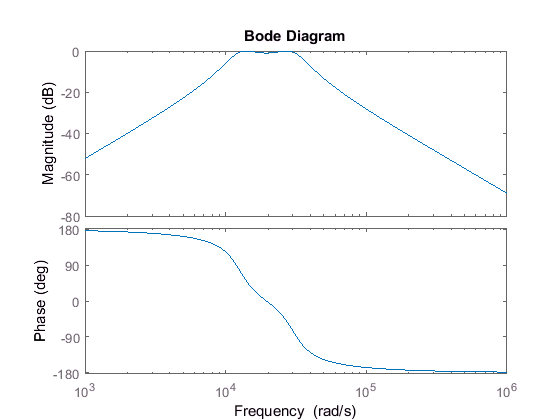

bode(Hsbp1*Hsbp2)